channel = 3; %RGB
kernel_size = 3;
ks2 = kernel_size^2;
offset = (kernel_size-1)/2;


img = cdata;%image path/filename
img_size = size(img,1);
is2 = img_size^2;
tic
img_p = gpuArray(zeros(img_size+(kernel_size-1),img_size+(kernel_size-1),channel,"single"));
img_p(1+offset:img_size+offset,1+offset:img_size+offset,:) = single(img)+rand(img_size,img_size,3,"single"); 
img_e = gpuArray(zeros(kernel_size,kernel_size,img_size,img_size,channel,"single"));


for i = 0:kernel_size*kernel_size-1
    x = floor(i/kernel_size);
    y = rem(i,kernel_size);
    img_e(x+1,y+1,:,:,:) = img_p(x+1:x+img_size,1+y:y+img_size,:);
end

[s,m] = std(img_e,0,[1 2]);
img_3d  = min(exp(-(img_e-m).^2./(2*s.^2)),[],5);


img_r = squeeze(sum(sum(img_e.*img_3d,[1 2]),5)./sum(img_3d,[1 2]));
img_r_p = gpuArray(zeros(img_size+kernel_size-1,img_size+kernel_size-1,"single"));
img_r_p(1+offset:img_size+offset,1+offset:img_size+offset) = img_r;

img_r_e = gpuArray(zeros(ks2,img_size,img_size,"single"));
for i = 0:ks2-1
    y = floor(i/kernel_size);
    x = rem(i,kernel_size);
    img_r_e(i+1,:,:)= img_r_p(x+1:x+img_size,1+y:y+img_size);
end

[~,ids] = sort(img_r_e,1);
ids = single(ids);
img_3d_s = reshape(img_3d,1,ks2*is2);
ids_s = reshape(ids(ks2,:,:),1,is2); % dilation
%ids_s = reshape(ids(1,:,:),1,is2); %  erosion
tmp = 0:1:is2-1;
tmp = single(tmp)*ks2;
ids_s = ids_s + tmp;
img_mod = img_3d_s(ids_s);
img_mod = reshape(img_mod,img_size,img_size);

img_dilated_p = gpuArray(zeros(img_size+kernel_size-1,img_size+kernel_size-1,"single"));
img_dilated_p(1+offset:img_size+offset,1+offset:img_size+offset) = img_mod;
img_dilated_e = gpuArray(zeros(kernel_size,kernel_size,img_size,img_size,"single"));

for i = 0:ks2-1
    x= floor(i/kernel_size);
    y= rem(i,kernel_size);
    img_dilated_e(x+1,y+1,:,:)= img_dilated_p(x+1:x+img_size,1+y:y+img_size);
end

img_mod = uint8(squeeze(sum(img_e.*img_dilated_e,[1 2])./sum(img_dilated_e,[1 2])));
toc

历时 1.123865 秒。


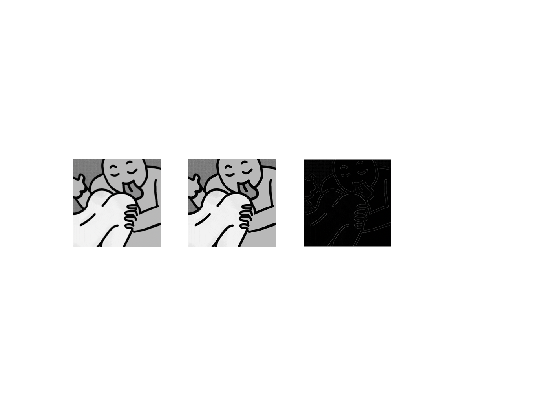

subplot(1,4,1)
imshow(imresize(img_mod,[224 224]))
subplot(1,4,2)
imshow(imresize(img,[224 224]))
subplot(1,4,3)
imshow(imresize(img_mod - img,[224 224]))
subplot(1,4,3)
imshow(imresize(img_mod - img,[224 224]))